# Supervised Machine Learning - Microstructural Defect Classification

Author: Ethan Edmunds

clc; clear; close all;

## 1.0 Pre-processing

### 1.1 Data Collection & Formatting

ds = readtable("defect_master_data.csv"); % Get dataset from csv file
ds = removevars(ds,{'id'}); % Remove the ID column as this isn't necessary
ds(1:5,:) % Show dataset

ans = 5×10 table
     area     major_axis    minor_axis    angle     circularity    feret_diameter    aspect_ratio    roundness    solidity    defect_type
    ______    __________    __________    ______    ___________    ______________    ____________    _________    ________    ___________

    432.05      69.555         7.909      81.798       0.143           85.075           8.795          0.114        0.51       {'Crack'} 
       538      80.915         8.466      154.72       0.126           94.744           9.558          0.105       0.474       {'Crack'} 
    138.91      25.235         7.009      16.517       0.478           25.538             

### 1.2 Data Analysis

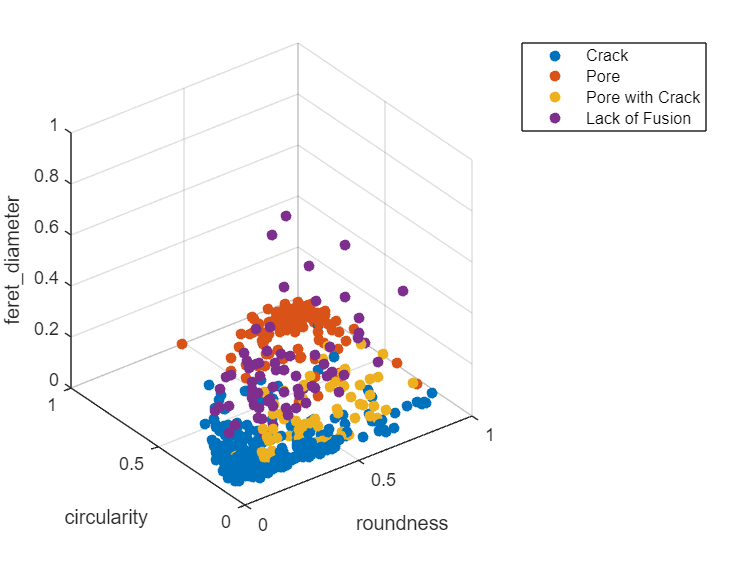

% Apply minimum-maximum normalisation to the dataset
ds_minMax = minMaxNorm(ds);

% Creating individual datasets for each type of defect
ds_minMax_crack = ds_minMax(ds_minMax.defect_type == "Crack", :);
ds_minMax_pore = ds_minMax(ds_minMax.defect_type == "Pore", :);
ds_minMax_pwc = ds_minMax(ds_minMax.defect_type == "Pore with Crack", :);
ds_minMax_lof = ds_minMax(ds_minMax.defect_type == "Lack of Fusion", :);

% Creating a 3D scatter plot to show variation of roundness, circularity,
% and feret_diameter for the different type of microstructural defects
figure
scatter3(ds_minMax_crack, "roundness", "circularity", "feret_diameter", "filled");
hold on
scatter3(ds_minMax_pore, "roundness", "circularity", "feret_diameter", "filled");
scatter3(ds_minMax_pwc, "roundness", "circularity", "feret_diameter", "filled");
scatter3(ds_minMax_lof, "roundness", "circularity", "feret_diameter", "filled");

legend(["Crack", "Pore", "Pore with Crack", "Lack of Fusion"])

### 1.3 Data Preparation

% Create training and test datasets to develop and evaluate the performance
% of the machine learning models using the createData function (as seen
% below)
[ds_train, ds_test] = createData(ds);

% Create a new dataset with minimum-maximum normalisation applied to the dataset
ds_minMax_train = minMaxNorm(ds_train);
ds_minMax_test = minMaxNorm(ds_test);

% Create a new datasset with z-Score normalisation applied to the
% dataset
ds_zScore_train = zScoreNorm(ds_train);
ds_zScore_test = zScoreNorm(ds_test);


## 2.0 KNN Classification

### 2.1 Finding Optimal K Value

In this segment, I experiment with the various parameters that could affect the performance of KNN classification algorithms. This involves varying the number of nearest neighbours 'K' as well as varying the normalisation method used to create the dataset. In this example, we are testing datasets with no normalisation applied, minimum-maximum normalisation, and z-score normalisation applied.

The algorithm will test the performance of each normalisation methods for various K values. Specificially, from 0 to 'maxK'. This can be varied.

maxK = 40; % Define maximum n value
knnAccuracy_kVariation = zeros(3,maxK); % Preallocate memory to hold accuracy readings for each

% Iterating through all integers from 0 to maxK. In each iteration, a model
% is trained using that value for K, labels are predicted using the model,
% and the knnAccuracy is recorded.
for i = 1:maxK
    
    knnModel = fitcknn(ds_train{:, 1:end-1}, ds_train{:, end}, "NumNeighbors", i); % Train the model with no normalisation
    knnModel_zScore = fitcknn(ds_zScore_train{:, 1:end-1}, ds_zScore_train{:, end}, "NumNeighbors", i); % Train the model with z-Score normalisation
    knnModel_minMax = fitcknn(ds_minMax_train{:, 1:end-1}, ds_minMax_train{:, end}, "NumNeighbors", i); % Train the model with minimum-maximum normalisation
    
    predicted_labels = predict(knnModel, ds_test{:, 1:end-1}); % Predict labels with no normalisation applied
    predicted_labels_zScore = predict(knnModel_zScore, ds_zScore_test{:, 1:end-1}); % Predict labels with z-Score normalisation applied
    predicted_labels_minMax = predict(knnModel_minMax, ds_minMax_test{:, 1:end-1}); % Predict labels with minimum-maximum noralisation applied

    knnAccuracy_kVariation(1, i) = sum(strcmp(predicted_labels, ds_test{:,end}))/numel(ds_test{:,end}); % Test the general accuracy for no normalisation applied
    knnAccuracy_kVariation(2, i) = sum(strcmp(predicted_labels_zScore, ds_test{:,end}))/numel(ds_test{:,end}); % Test the general accuracy for z-Score normalisation
    knnAccuracy_kVariation(3, i) = sum(strcmp(predicted_labels_minMax, ds_test{:,end}))/numel(ds_test{:,end}); % Test the general accuracy for minimum-maximum normalisation

end

% Find the respective average accuracies accross all K values for no
% normalisation, z-Score normalisation and minimum-maximum normalisation
% applied
avgNoNorm = mean(knnAccuracy_kVariation(1,:));
avgZScore = mean(knnAccuracy_kVariation(2,:));
avgMinMax = mean(knnAccuracy_kVariation(3,:));

% Print the maximum and average accuracies for each normalisation
% technique
fprintf("The average accuracy for the model without normalisation is " + avgNoNorm*100)

The average accuracy for the model without normalisation is 71.4286

fprintf("The average accuracy for the model with zScore is " + avgZScore*100)

The average accuracy for the model with zScore is 85.8143

fprintf("The average accuracy for the model with minMax is " + avgMinMax*100)

The average accuracy for the model with minMax is 81.4143

fprintf("The maximum accuracy for the model without normalisation is " + max(knnAccuracy(1,:))*100)

The maximum accuracy for the model without normalisation is 79.4286

fprintf("The maximum accuracy for the model with zScore is " + max(knnAccuracy(2,:))*100)

The maximum accuracy for the model with zScore is 90.2857

fprintf("The maximum accuracy for the model with minMax is " + max(knnAccuracy(3,:))*100)

The maximum accuracy for the model with minMax is 84

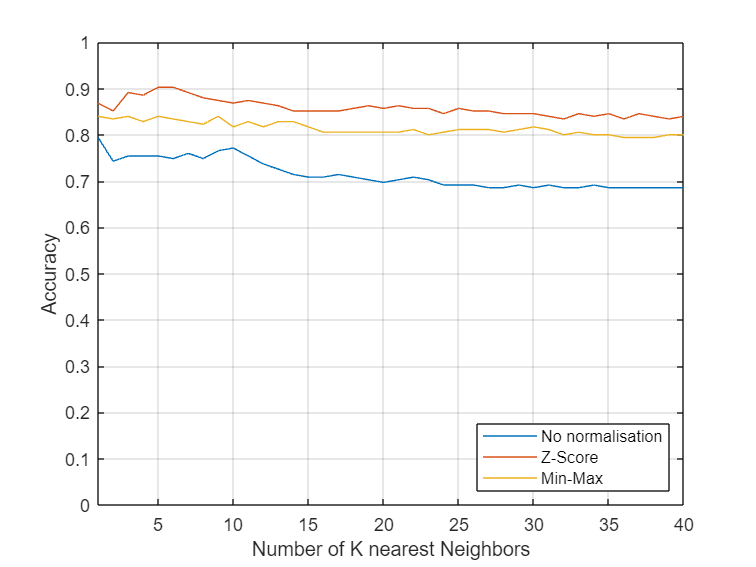

The maximum accuracy observed is 0.90286 for Z score normalisation when K is equal to 5


% Plot the variation of accuracy with K nearest neighbor for each
% normalised data set
figure
plot(knnAccuracy(1,:));
hold on
plot(knnAccuracy(2,:));
plot(knnAccuracy(3,:));
hold off
xlabel("Number of K nearest Neighbors");
ylabel("Accuracy");
legend(["No normalisation", "Z-Score", "Min-Max"], Location="southeast");
ylim([0 1])
grid on
xlim([1 maxK])
saveas(gcf,'K-variation.png')

% We know that z-Score normalisation typically exhibits the highest
% accuracy so we can find the K value and the maximum accuracy that the K
% value yields
[maxAccuracyKNN, maximumIndexKNN] = max(knnAccuracy(2,:));
disp("The maximum accuracy observed is " + maxAccuracyKNN + " for Z score normalisation when K is equal to " + maximumIndexKNN);

### 2.2 Variation of accuracy with randomised datasets

Due to it's structure, the algorithm yields a randomised training and testing dataset each time it is executed. This can lead to sometimes very significant variations in performance of the algorithm. For that reason, I want to see the 'average' performance of the KNN classification algorithm. This way, we can evaluate on average, which normalisation method works best for the KNN classification algorithm.

% Number of iterations to run
i_max = 500;

kNN_iter_accuracyData = zeros(i_max, 3); % Preallocating memory space to hold accuracy for kNN Classification algorithm

% This for loop will iterate from 1 to 500
for i = 1:i_max

    % Randomly create train and test datasets for the various normalisation
    % techniques that were previously discussed
    [ds_train_iter, ds_test_iter] = createData(ds);
    ds_zScore_train_iter = zScoreNorm(ds_train_iter);
    ds_minMax_train_iter = minMaxNorm(ds_train_iter);
    ds_zScore_test_iter = zScoreNorm(ds_test_iter);
    ds_minMax_test_iter = minMaxNorm(ds_test_iter);

    maxK = 20; % Define maximum k value
    knnAccuracy = zeros(3,maxK); % Preallocate memory to hold accuracy readings for each
    
    % Testing each normalisation methods' accuracy with respect to the K
    % value used to train the model
    for j = 1:maxK

        % Train kNN classification model given k value
        knnModel_iter = fitcknn(ds_train_iter{:, 1:end-1}, ds_train_iter{:, end}, "NumNeighbors", j);
        knnModel_zScore_iter = fitcknn(ds_zScore_train_iter{:, 1:end-1}, ds_zScore_train_iter{:, end}, "NumNeighbors", j);
        knnModel_minMax_iter = fitcknn(ds_minMax_train_iter{:, 1:end-1}, ds_minMax_train_iter{:, end}, "NumNeighbors", j);

        % Predict the labels of test dataset
        predicted_labels_iter = predict(knnModel_iter, ds_test_iter{:, 1:end-1});
        predicted_labels_zScore_iter = predict(knnModel_zScore_iter, ds_zScore_test_iter{:, 1:end-1});
        predicted_labels_minMax_iter = predict(knnModel_minMax_iter, ds_minMax_test_iter{:, 1:end-1});
        
        % Find the overall accuracy of the machine learning model
        knnAccuracy(1, i) = sum(strcmp(predicted_labels_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});
        knnAccuracy(2, i) = sum(strcmp(predicted_labels_zScore_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});
        knnAccuracy(3, i) = sum(strcmp(predicted_labels_minMax_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});

    end

    % Save accuracy data to matrix
    kNN_iter_accuracyData(i, :) = [max(knnAccuracy(1,:)) max(knnAccuracy(2,:)) max(knnAccuracy(3,:))];
    fprintf(kNN_iter_accuracyData(i, 1) + " " + kNN_iter_accuracyData(i, 2) + " " + kNN_iter_accuracyData(i, 3) + " ... Iteration " + i + " complete...\n")

end

% Reveal the mean and standard deviation of accuracies for different
% normalisation methods
accuracyStats = [mean(kNN_iter_accuracyData(:,1)) std(kNN_iter_accuracyData(:,1)); mean(kNN_iter_accuracyData(:,2)) std(kNN_iter_accuracyData(:,2)); mean(kNN_iter_accuracyData(:,3)) std(kNN_iter_accuracyData(:,3))] 

% Create a boxplot to summarise the performance of each algorithm over 500
% iterations with randomised datasets
figure
boxplot([kNN_iter_accuracyData(:,1) kNN_iter_accuracyData(:,2) kNN_iter_accuracyData(:,3)],'Labels',{'No Normalisation','z-Score', 'Min-max'});
xlabel('Normalisation Method')
ylabel('Accuracy')
set(gca, 'XGrid','on')
saveas(gcf,'KNNBoxPlot.png')
%}


### 2.3 KNN Classification Algorithms - Confusion Matrices

Now we use the original dataset, to create confusion matrices for the optimal K value that was found in Section 2.1

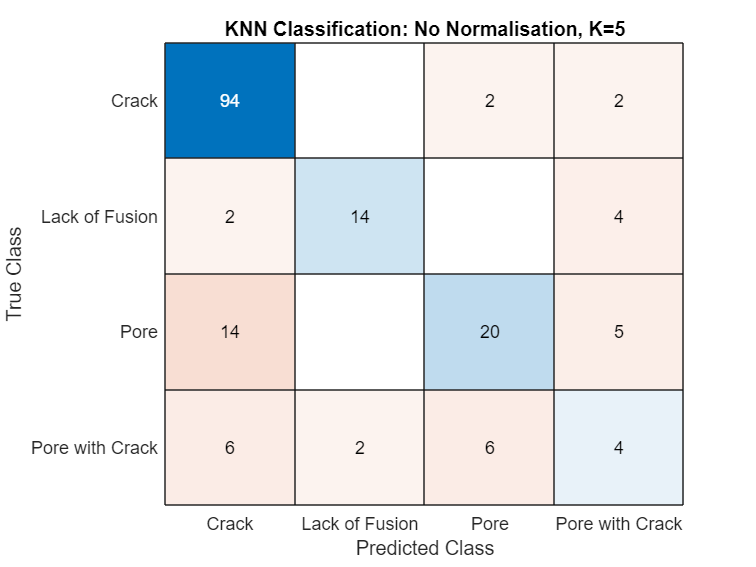

% Develop confusion matrix for no normalisation, using KNN
knnModel_noNorm_optimal = fitcknn(ds_train{:, 1:end-1}, ds_train{:, end}, "NumNeighbors", maximumIndexKNN);
knnPredlabels_noNorm = predict(knnModel_noNorm_optimal, ds_test{:, 1:end-1});

% Plot confusion matrix
figure;
confusion_KNNoptimal_noNorm = confusionmat(ds_test{:, end}, knnPredlabels_noNorm);
confusionchart(ds_test{:, end}, knnPredlabels_noNorm);
title("KNN Classification: No Normalisation, K=" + maximumIndexKNN)
saveas(gcf,'KNNClassificationNoNorm.png')

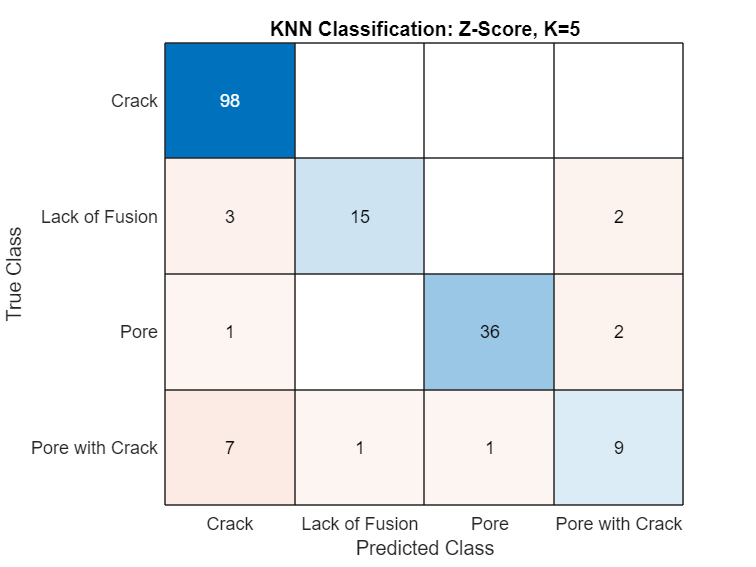

% Develop confusion matrix for zScore normalisation, using KNN
knnModel_zScore_optimal = fitcknn(ds_zScore_train{:, 1:end-1}, ds_zScore_train{:, end}, "NumNeighbors", maximumIndexKNN);
knnPredlabels_zScore = predict(knnModel_zScore_optimal, ds_zScore_test{:, 1:end-1});

% Plot confusion matrix
figure;
confusion_KNNoptimal = confusionmat(ds_test{:, end}, knnPredlabels_zScore);
confusionchart(ds_test{:, end}, knnPredlabels_zScore);
title("KNN Classification: Z-Score, K=" + maximumIndexKNN)
saveas(gcf,'KNNClassificationZScore.png')

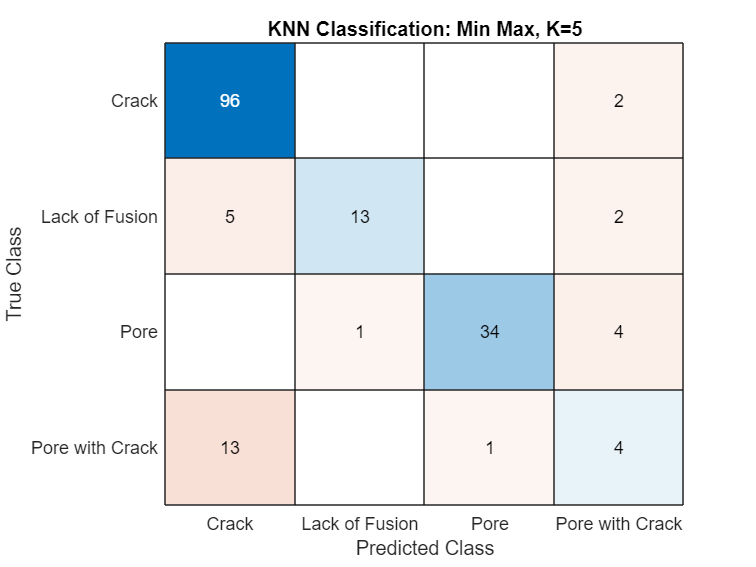

% Develop confusion matrix for minMax normalisation, using KNN when
knnModel_minMax_optimal = fitcknn(ds_minMax_train{:, 1:end-1}, ds_minMax_train{:, end}, "NumNeighbors", maximumIndexKNN);
knnPredlabels_minMax = predict(knnModel_minMax_optimal, ds_minMax_test{:, 1:end-1});
% Plot confusion matrix
figure;
confusion_KNNoptimal_minMax = confusionmat(ds_test{:, end}, knnPredlabels_minMax);
confusionchart(ds_test{:, end}, knnPredlabels_minMax);
title("KNN Classification: Min Max, K=" + maximumIndexKNN)
saveas(gcf,'KNNClassificationMinMax.png')

## 3.0 Decision Trees

Decision trees don't have any parameters that need to be tested, so we can just create confusion matrices using the original dataset. We can also test the variation of performance with randomised training and testing datasets in a similar fashion to that of KNN classification

% Training a decision tree model on datasets producing each normalisation
% technique
dTreeModel = fitctree(ds_train{:, 1:end-1}, ds_train{:, end});
dTreeModel_zScore = fitctree(ds_zScore_train{:, 1:end-1}, ds_zScore_train{:, end});
dTreeModel_minMax = fitctree(ds_minMax_train{:, 1:end-1}, ds_minMax_train{:, end});

% Creating an array of predictions based off the original datasets with
% decision tree models
predicted_labels = predict(dTreeModel, ds_test{:, 1:end-1});
predicted_labels_zScore = predict(dTreeModel_zScore, ds_zScore_test{:, 1:end-1});
predicted_labels_minMax = predict(dTreeModel_minMax, ds_minMax_test{:, 1:end-1});

% Create a confusion matrix for each normalisation method
confusionMat_dTree_noNormal = confusionmat(ds_test{:, end}, predicted_labels);
confusionMat_dTree_zScore = confusionmat(ds_zScore_test{:, end}, predicted_labels_zScore);
confusionMat_dTree_minMax = confusionmat(ds_minMax_test{:, end}, predicted_labels);

% Plot the respective confusion matrices for the different models
figure
confusionchart(ds_test{:, end}, predicted_labels)
title("Decision Tree: No Normalisation")
saveas(gcf,'DecisionTreeNoNorm.png')

figure
confusionchart(ds_zScore_test{:, end}, predicted_labels_zScore)

similarity = 0.8571

title("Decision Tree: z-Score")

saveas(gcf,'DecisionTreeZScore.png')
figure
confusionchart(ds_minMax_test{:, end}, predicted_labels)
title("Decision Tree: Min Max")
saveas(gcf,'DecisionTreeMinMax.png')

### 3.1 Variation of accuracy with randomised datasets

dTreeAccuracy = zeros(i_max, 3); % Preallocating memory space to hold accuracy for kNN Classification algorithm

for i = 1:i_max
    
    % Randomly create training and testing datasets using the createData
    % function as described below
    [ds_train_iter, ds_test_iter] = createData(ds);
    ds_zScore_train_iter = zScoreNorm(ds_train_iter);
    ds_minMax_train_iter = minMaxNorm(ds_train_iter);
    ds_zScore_test_iter = zScoreNorm(ds_test_iter);
    ds_minMax_test_iter = minMaxNorm(ds_test_iter);

    % Training the model for each of the datasets created above
    dTreeModel_iter = fitctree(ds_train_iter{:, 1:end-1}, ds_train_iter{:, end});
    dTreeModel_zScore_iter = fitctree(ds_zScore_train_iter{:, 1:end-1}, ds_zScore_train_iter{:, end});
    dTreeModel_minMax_iter = fitctree(ds_minMax_train_iter{:, 1:end-1}, ds_minMax_train_iter{:, end});

    % Developing predictions using the respective models with different
    % normalisation techniques applied
    predicted_labels_iter = predict(dTreeModel_iter, ds_test_iter{:, 1:end-1});
    predicted_labels_zScore_iter = predict(dTreeModel_zScore_iter, ds_zScore_test_iter{:, 1:end-1});
    predicted_labels_minMax_iter = predict(dTreeModel_minMax_iter, ds_minMax_test_iter{:, 1:end-1});
    
    % Allocate their accuracy to the matrix
    dTreeAccuracy(i, 1) = sum(strcmp(predicted_labels_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});
    dTreeAccuracy(i, 2) = sum(strcmp(predicted_labels_zScore_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});
    dTreeAccuracy(i, 3) = sum(strcmp(predicted_labels_minMax_iter, ds_test_iter{:,end}))/numel(ds_test_iter{:,end});

    fprintf(dTreeAccuracy(i, 1) + " " + dTreeAccuracy(i, 2) + " " + dTreeAccuracy(i, 3) + " ... Iteration " + i + " complete...\n")
end

% Create a table summarising the statistical information about the decision
% tree accuracy
accuracyStatsDTree = [mean(dTreeAccuracy(:,1)) std(dTreeAccuracy(:,1)); mean(dTreeAccuracy(:,2)) std(dTreeAccuracy(:,2)); mean(dTreeAccuracy(:,3)) std(dTreeAccuracy(:,3))] 

% Create a boxplot to summarise performance variation in machine learning
% model
figure
boxplot([dTreeAccuracy(:,1) dTreeAccuracy(:,2) dTreeAccuracy(:,3)],'Labels',{'No Normalisation','z-Score', 'Min-max'});
grid on
xlabel('Normalisation Method')
ylabel('Accuracy')
saveas(gcf,'DTreeBoxPlot.png')

## 4.0 Functions

Function that splits a dataset into training data and test data (with even distribution in labels)

function [trainData, testData] = createData(table)

    trainData = array2table(zeros(0,10));
    trainData.Properties.VariableNames = table.Properties.VariableNames;
    testData = array2table(zeros(0,10));
    testData.Properties.VariableNames = table.Properties.VariableNames;

    labels = unique(table.defect_type);
    
    for i = 1:length(labels)
        
        data = table(ismember(table.defect_type, labels(i)), :);
        n = length(data.defect_type);
        cv = cvpartition(n, "HoldOut", 0.3);

        idxTrain = training(cv);
        tblTrain = data(idxTrain, :);
        idxTest = test(cv);
        tblTest = data(idxTest, :);

        trainData = [trainData; tblTrain];
        testData = [testData; tblTest];

    end

end

Function that normalises the data via z-Score transformation

function ds_zScore = zScoreNorm(ds)

    [row, col] = size(ds); % Get size of numerical dataset
    ds_zScore = ds;

    % Transform the original data in zScored data
    for i = 1:col-1
        avg = mean(ds{:,i});
        sd = std(ds{:,i});
        for j = 1:row
            ds_zScore{j,i} = (ds{j,i}-avg)/sd;
        end
    end

end

Function that normalises a dataset via minimum-maximum transformation

function ds_minMax = minMaxNorm(ds)
    % Transform the original data into Min Max data
    
    [row, col] = size(ds); % Get size of numerical dataset
    ds_minMax = ds;

    for i = 1:col-1
        minCol = min(ds{:,i});
        maxCol = max(ds{:,i});

        for j = 1:row
            ds_minMax{j,i} = (ds{j,i}-minCol)/(maxCol-minCol);
        end
    end
    
end